close all
clc
clear 


%% 参数初始化
c1 = 2;c2 = 2;%速度更新参数
maxgen = 300;%迭代次数
sizepop = 20;%粒子数量/种群大小
Vmax = 0.5;Vmin = -0.5;%粒子的最大和最小速度，这个可以根据自己的需求定义
popmax = 2;popmin = -2;%粒子的最大和最小位置，即x的取值范围，或者说是粒子的搜索范围
dim = 1;%维度，可以理解为自变量数
ws = 0.9;%初始惯性权重
we = 0.4;%迭代至最大次数时的惯性权重
%% 开始100次试验
for g =1:100  %假设有100个这样的种群同时在进化/或者说这个种群重复100次进化
    %% 随机初始化粒子速度和粒子位置(先速度后位置)，并根据适应度函数计算粒子适应度值
    g   %第g次试验
    for i = 1:sizepop %20个粒子，每个都要初始化
        %随机产生一个种群
        pop(i,:) = 2*rands(1,dim);%将粒子位置都随机分布在-2~2之间
        V(i,:) = 0.5*rands(1,dim);%将粒子速度都随机分布在-0.5~0.5之间
        
        %计算粒子/个体适应度值
        fitness(i) = myfitness1(pop(i,:));%将粒子位置代入适应度函数(这里2个变量/2维)，求解出粒子适应度值
    end
    
    %% 寻找初值个体极值和群体极值，用于后续迭代过程
    [bestfitness,bestindex] = max(fitness);
    gbest = pop;%因为是初始时刻，所以个体极值位置/所有粒子最好位置的集合，就是初始时刻粒子位置的集合
    fitnessgbest = fitness;%个体适应度值，即初始时刻(此次迭代)所有个体/粒子位置代入适应度函数得到适应度函数的最大/小取值
    zbest = pop(bestindex,:);%群体极值位置，即初始时刻(此次迭代)是群体中最好的那个粒子位置
    fitnesszbest = bestfitness;%群体适应度值/群体极值，即初始时刻(此次迭代)是群体中最好粒子位置代入适应度函数得到适应度函数的最大/小取值
    
    %% 迭代寻优
    for k = 1:maxgen
            %计算惯性权重
%             w = 1;%常数惯性权重因子
            w = ws*(ws-we)*(maxgen-k)/maxgen;%线性递减惯性权重
%             w = ws-(ws-we)*(k/maxgen);%非线性递减惯性权重①
%             w = ws-(ws-we)*(k/maxgen)^2;%非线性递减惯性权重②
%             w = ws+(ws-we)*(2*k/maxgen-(k/maxgen)^2);%非线性递减惯性权重③
%             w = we*(ws/we)^(1/(1+10*k/maxgen));%非线性递减惯性权重④
 
        %粒子位置和速度更新
        for i = 1:sizepop
            
            %速度更新
            V(i,:) = w*V(i,:)+c1*rand*(gbest(i,:)-pop(i,:))+c2*rand*(zbest-pop(i,:));
            flagVub = find(V(i,:) > Vmax);%找出迭代过程中超出最大速度的粒子的列数，这里2维，所以有：
            %如果粒子的第一个维度的速度 > Vmax，则find(V(i,:) > Vmax)=[1,0]
            %如果粒子的第二个维度方向的速度 > Vmax，则find(V(i,:) > Vmax)=[0,2]
            %如果两个维度速度都＞Vmax，则为[1,2]
            V(i,flagVub) = Vmax;
            flagVlb = find(V(i,:) < Vmin);%同理找出迭代过程中小于最小速度粒子的列数
            V(i,flagVlb) = Vmin;
            
            %位置更新
            pop(i,:) = pop(i,:)+V(i,:);%
            flagXub = find(pop(i,:) > popmax);
            pop(i,flagXub) = popmax;%同理如果位置某个维度的位置>最大位置，则该次迭代产生的粒子该维度位置=最大位置
            flagXlb = find(pop(i,:) < popmin);
            pop(i,flagXlb) = popmin;
            
            %产生的新粒子适应度值
            fitness(i) = myfitness1(pop(i,:));
        end
        
        %个体极值和群体极值更新
        for j = 1:sizepop
            
            %个体极值更新
            if fitness(j) > fitnessgbest(j)%注：因为个体极值是一维数组，所以要一个索引下标
                gbest(j,:) = pop(j,:);
                fitnessgbest(j) = fitness(j);
            end
            
            %群体极值更新
            if fitness(j) > fitnesszbest%注：因为个体极值是一个数，所以不需要索引值
                zbest = pop(j,:);
                fitnesszbest = fitness(j);
            end
        end
        result(k) = fitnesszbest;%记录群体极值，即目标函数最优解
        
    end
    s(g,:)=result;%重复100次试验+本身1次，所以最终k = 101
end

g = 1

g = 2

g = 3

g = 4

g = 5

g = 6

g = 7

g = 8

g = 9

g = 10

g = 11

g = 12

g = 13

g = 14

g = 15

g = 16

g = 17

g = 18

g = 19

g = 20

g = 21

g = 22

g = 23

g = 24

g = 25

g = 26

g = 27

g = 28

g = 29

g = 30

g = 31

g = 32

g = 33

g = 34

g = 35

g = 36

g = 37

g = 38

g = 39

g = 40

g = 41

g = 42

g = 43

g = 44

g = 45

g = 46

g = 47

g = 48

g = 49

g = 50

g = 51

g = 52

g = 53

g = 54

g = 55

g = 56

g = 57

g = 58

g = 59

g = 60

g = 61

g = 62

g = 63

g = 64

g = 65

g = 66

g = 67

g = 68

g = 69

g = 70

g = 71

g = 72

g = 73

g = 74

g = 75

g = 76

g = 77

g = 78

g = 79

g = 80

g = 81

g = 82

g = 83

g = 84

g = 85

g = 86

g = 87

g = 88

g = 89

g = 90

g = 91

g = 92

g = 93

g = 94

g = 95

g = 96

g = 97

g = 98

g = 99

g = 100

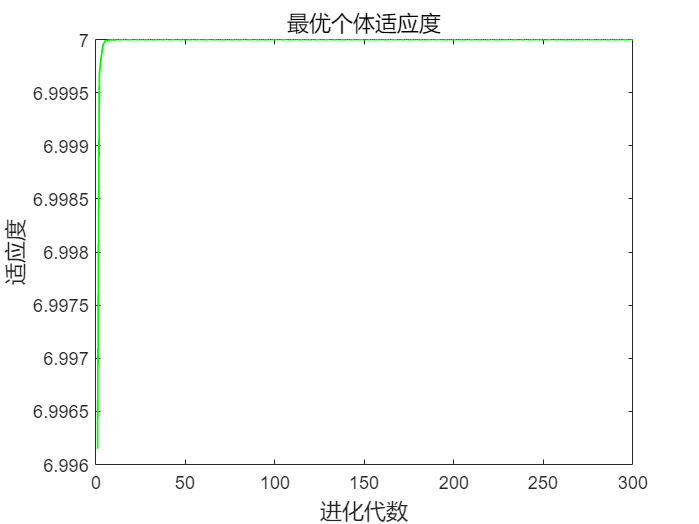

 
%% 绘图
%画出每代最优个体适应度值
for m=1:300
    s(101,m)=sum( s(:,m) )/100;%将100次试验的个体适应度值放在最后一行
end
figure(1)
plot(s(101,:),'g','linewidth',1)
title('最优个体适应度','fontsize',12);
xlabel('进化代数','fontsize',12);ylabel('适应度','fontsize',12);

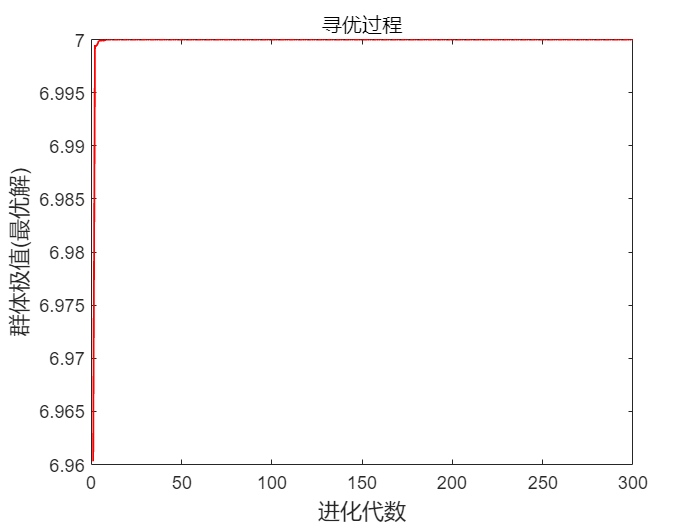

 
%画出整个迭代的寻优过程
figure(2)
plot(result,'r','linewidth',1)
title('寻优过程')
xlabel('进化代数','fontsize',12);ylabel('群体极值(最优解)','fontsize',12);

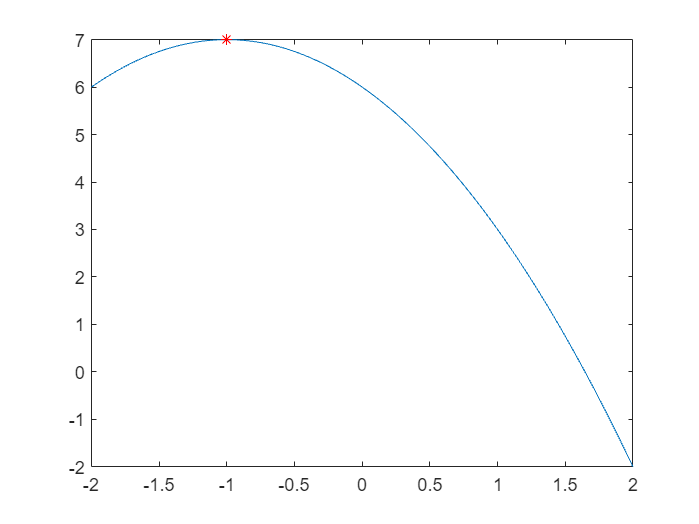

 
%画出目标函数三维图像
figure(3)
x=(-2:0.01:2);
y=-x.^2-2.*x+6;
% z=sin( sqrt(x.^2+y.^2) )./sqrt(x.^2+y.^2)+exp((cos(2*pi*x)+cos(2*pi*y))/2)-2.71289;
% mesh(x,y,z)
plot(x,y)
hold on
plot(zbest,fitnesszbest,'*r')

function y = myfitness1(x)
%x    输入粒子的位置
%y    输出粒子适应度值
y=-x^2-2*x+6;
%y=-(sin( sqrt(x(1).^2+x(2).^2) )./sqrt(x(1).^2+x(2).^2)+exp((cos(2*pi*x(1))+cos(2*pi*x(2)))/2)-2.71289);
end
